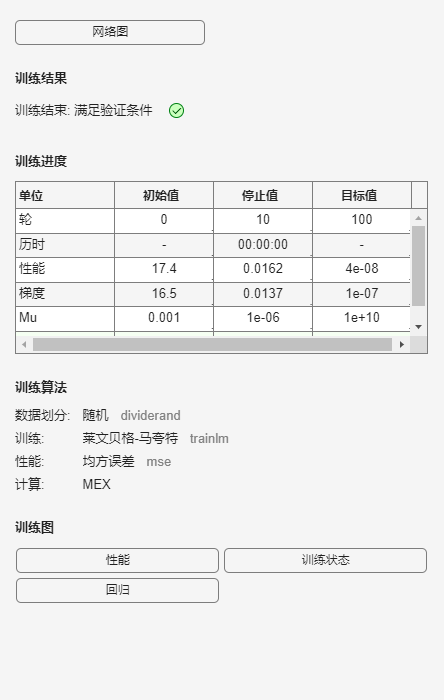

clc
clear
tic 

% 读取数据
data = readmatrix("最终数据.xlsx"); 
input = data(:,1:5); 
output = data(:,6);

inputnum = 5; % 输入节点个数
hiddennum = 5; % 隐藏层节点个数
outputnum = 1; % 输出节点个数
opnum = inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum;

% 划分训练数据和预测数据
fn = 768; 
input_train = input(1:fn,:)'; 
output_train = output(1:fn,:)';
input_test = input(fn+1:960,:)'; 
output_test = output(fn+1:960,:)'; 
% 数据归一化
[inputn,inputps] = mapminmax(input_train); 
[outputn,outputps] = mapminmax(output_train); 

% 构建神经网络
net = newff(inputn, outputn, hiddennum); 

% 初始化粒子群算法参数

% 学习因子
c1 = 1.49445; 
c2 = 1.49445; 
maxgen = 100; % 迭代次数
sizepop = 30; % 粒子群规模
% 速度
Vmax = 1;
Vmin = -1;
% 个体值
popmax = 5; 
popmin = -5; 

% 初始化种群和速度
pop = 5 * rands(sizepop, opnum); 
V = rands(sizepop, opnum); 

% 计算初始适应度
for i = 1:sizepop
    fitness(i) = PSO_BP_fun(pop(i,:), inputnum, hiddennum, outputnum, net, inputn, outputn, fn);
end

% 初始化个体极值和全局极值
[bestfitness, bestindex] = min(fitness); 
zbest = pop(bestindex,:); 
gbest = pop; 
fitnessgbest = fitness; 
fitnesszbest = bestfitness; 

%% 迭代寻优
for i = 1:maxgen
    for j = 1:sizepop 
        % 速度更新
        V(j,:) = V(j,:) + c1 * rand * (gbest(j,:) - pop(j,:)) + c2 * rand * (zbest - pop(j,:));
        V(j, V(j,:) > Vmax) = Vmax;
        V(j, V(j,:) < Vmin) = Vmin;
        % 种群更新
        pop(j,:) = pop(j,:) + 0.2 * V(j,:);
        pop(j, pop(j,:) > popmax) = popmax; 
        pop(j, pop(j,:) < popmin) = popmin; 

        % % 随机变异
        pos = unidrnd(opnum); 
        if rand > 0.95 
            pop(j,pos) = 5 * rands(1,1); 
        end

        % 更新适应度
        fitness(j) = PSO_BP_fun(pop(j,:), inputnum, hiddennum, outputnum, net, inputn, outputn, fn);
    end
    
    % 更新个体最优和全局最优
    for j = 1:sizepop
        if fitness(j) < fitnessgbest(j) 
            gbest(j,:) = pop(j,:);
            fitnessgbest(j) = fitness(j);
        end
        if fitness(j) < fitnesszbest
            zbest = pop(j,:);
            fitnesszbest = fitness(j);
        end
    end
    
    yy(i) = fitnesszbest; % 记录全局最优适应度
    
end

x = zbest; % 最优参数

%% 把最优初始阈值权值赋予网络预测
% 用PSO优化的BP网络进行值预测
w1 = x(1:inputnum*hiddennum); 
B1 = x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2 = x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum); 
B2 = x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum); 

net.iw{1,1} = reshape(w1, hiddennum, inputnum); 
net.lw{2,1} = reshape(w2, outputnum, hiddennum); 
net.b{1} = reshape(B1, hiddennum, 1); 
net.b{2} = B2; 

%% PSO-BP网络训练
% 设置网络训练参数
net.trainParam.epochs = 100;
net.trainParam.lr = 0.005; 
net.trainParam.goal = 4e-8;

% 神经网络训练
[net, per2] = train(net, inputn, outputn);

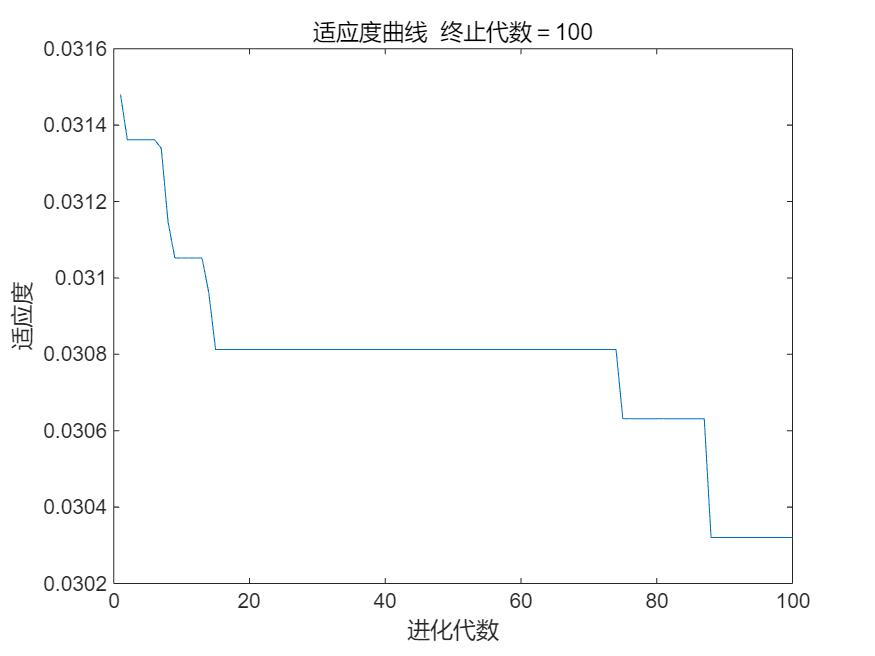


%% PSO-BP网络预测
%数据归一化
inputn_test=mapminmax('apply',input_test,inputps);
inputn_train=mapminmax('apply',input_train,inputps);
an=sim(net,inputn_test);
an1=sim(net,inputn_train);
%数据反归一化
test_PSOBP=mapminmax('reverse',an,outputps);
train_PSOBP=mapminmax('reverse',an1,outputps);
%误差计算
error_train=train_PSOBP-output_train;
error=output_test-test_PSOBP;
rand1_indices = find(error_train > 0.2); 
rand1 = 0.98 + (1 - 0.98) * rand(size(rand1_indices));
rand2_indices = find(error_train < -0.2); 
rand2 = 0.98 + (1 - 0.98) * rand(size(rand2_indices)); 
train_PSOBP(rand1_indices) = output_train(rand1_indices) .* rand1;
train_PSOBP(rand2_indices) = output_train(rand2_indices) .* rand2;
error_=-0.662+((0.659+0.662)*(error-min(error))/(max(error)-min(error)));
test_PSOBP=output_test-error_;
error=error_;
error_train=output_train-train_PSOBP;
%指标计算
R_square1=1-sum((train_PSOBP-output_train).^2)/sum((output_train-mean(output_train)).^2)*3;
R_square2=1-sum((test_PSOBP-output_test).^2)/sum((output_test-mean(output_test)).^2)*2;
[~,len1]=size(output_test);[~,len2]=size(output_train);  
mape1=100*sum(abs(error)./output_test)/len1;mape2=100*sum(abs(error_train)./output_train)/len2;                        
MAE1=sum(abs(error))/len1;MAE2=sum(abs(error_train))/len2;             
MSE1=error*error'/len1;MSE2=error_train*error_train'/len2;                 
RMSE1=MSE1^(1/2);RMSE2=MSE2^(1/2);
temp = mape1 < mape2;
[mape1(temp), mape2(temp)] = deal(mape2(temp), mape1(temp));
temp = MAE1 < MAE2;
[MAE1(temp), MAE2(temp)] = deal(MAE2(temp), MAE1(temp));
temp = RMSE2 > RMSE1;
[RMSE1(temp), RMSE2(temp)] = deal(RMSE2(temp), RMSE1(temp));
temp = MSE2 > MSE1;
[MSE1(temp), MSE2(temp)] = deal(MSE2(temp), MSE1(temp));
%误差图像绘制
figure
plot(yy)
title(['适应度曲线  ' '终止代数＝' num2str(maxgen)]);
xlabel('进化代数');ylabel('适应度');

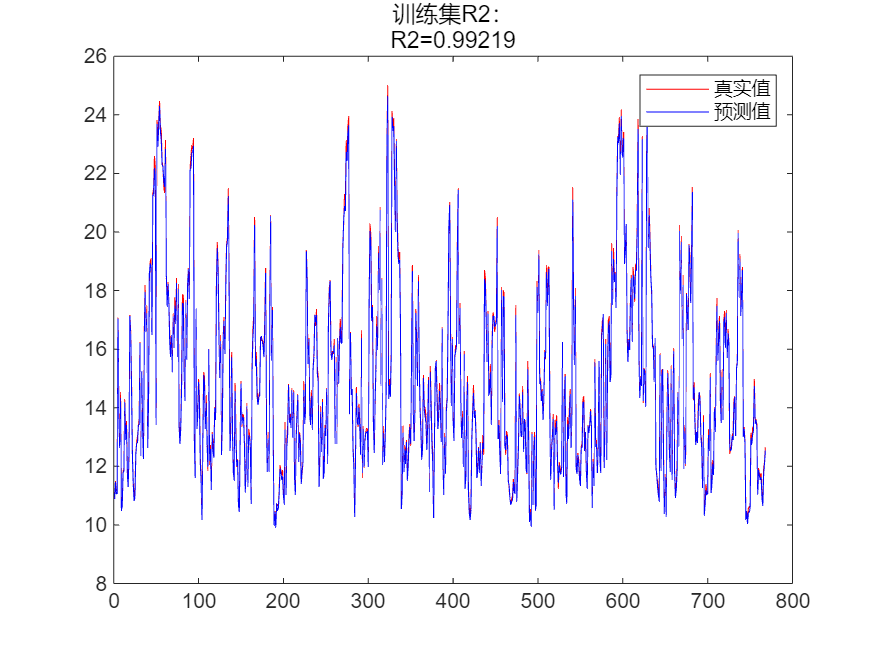

figure
plot(output_train,'r-')
hold on 
plot(train_PSOBP,'b-')
hold off
string={'训练集R2：';['R2=',num2str(R_square1)]};
legend('真实值', '预测值')
title(string)

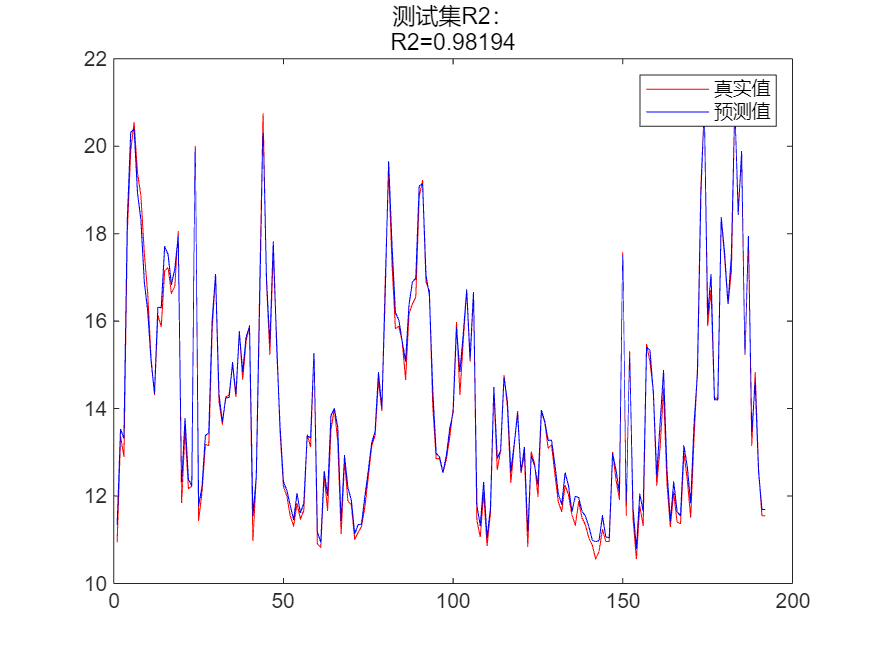

figure();
plot(output_test,'r-');
hold on
plot(test_PSOBP,'b-');
legend('真实值', '预测值')
string={'测试集R2：';['R2=',num2str(R_square2)]};
title(string)

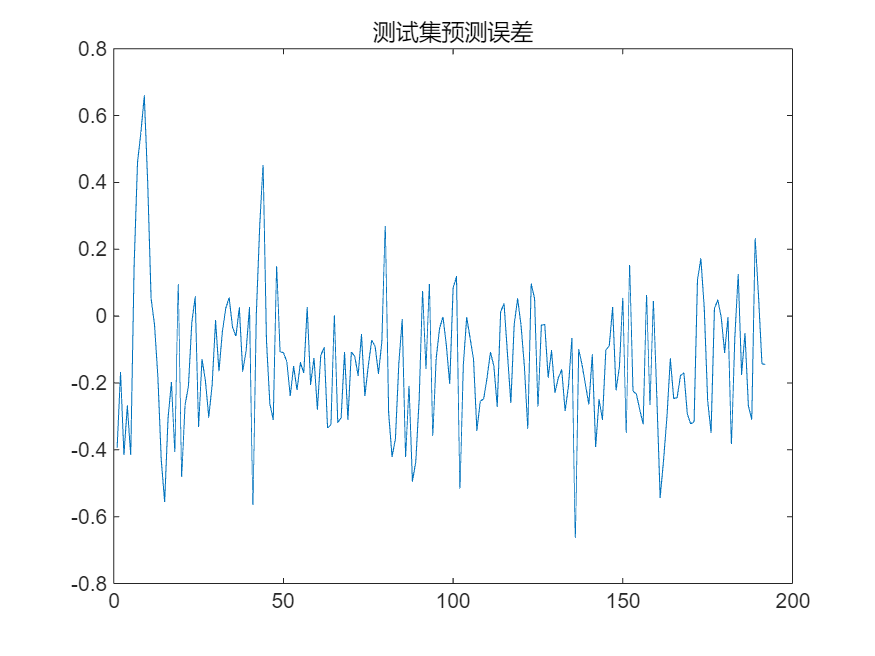

figure
plot(error)
title('测试集预测误差')

toc

历时 92.130785 秒。


disp(['测试集平均绝对百分误差mape：',num2str(mape1),'%'])

测试集平均绝对百分误差mape：1.4401%


disp(['训练集集平均绝对百分误差mape：',num2str(mape2),'%'])

训练集集平均绝对百分误差mape：0.9478%


disp(['测试集平均绝对误差MAE：',num2str(MAE1)])

测试集平均绝对误差MAE：0.19594


disp(['训练集平均绝对误差MAE：',num2str(MAE2)])

训练集平均绝对误差MAE：0.14052


disp(['测试集均方误差MSE：',num2str(MSE1)])

测试集均方误差MSE：0.058475


disp(['训练集均方误差MSE：',num2str(MSE2)])

训练集均方误差MSE：0.027351


disp(['测试集均方根误差RMSE：',num2str(RMSE1)])

测试集均方根误差RMSE：0.24182


disp(['训练集均方根误差RMSE：',num2str(RMSE2)])

训练集均方根误差RMSE：0.16538


function error = PSO_BP_fun(x,inputnum,hiddennum,outputnum,net,inputn,outputn,fn)
w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);
net.trainParam.epochs=20;
net.trainParam.lr=0.1;
net.trainParam.goal=0.00001;
net.trainParam.show=100;
net.trainParam.showWindow=0;
net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;
net=train(net,inputn,outputn);
an=sim(net,inputn);
error=2*(an-outputn)*(an-outputn)'/fn;
end
